  clear 


x_moto = [2,3,1,4,5,7,6,9,23,45,777,88,43]

x_moto =      2     3     1     4     5     7     6     9    23    45   777    88    43



K = fix(log2(length(x_moto)))+1

K = 4


L = 2.^[0:K-1]

L =      1     2     4     8



x= zeros(1,1000);
x(1:length(x_moto))=x_moto;

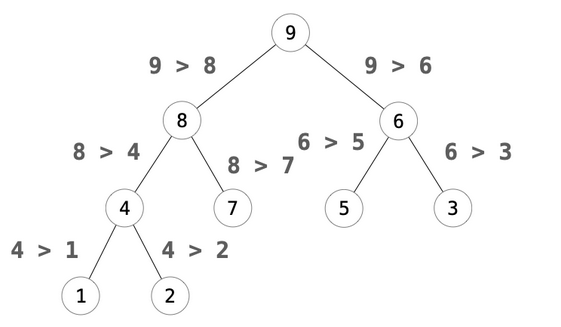

2分岐の作成


x

x =      2     3     1     4     5     7     6     9    23    45   777    88    43     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for u=1:length(x_moto)
u
        for ll=2:length(L) 
         l=6-ll; % 階層レベル 下の階層から処理する。
         K=l-2; 
           for k=0:K   
             m=2*k; % m,n:2分岐の右左, k:階層のどの位置か
             n=m+1;
                if x(L(l)+m) < x(L(l)+n) % 左が大きいにする。
                    tmp = x(L(l)+m);
                    x(L(l)+m) = x(L(l)+n);
                    x(L(l)+n) = tmp;
                end
            
                if x(L(l-1)+k) < x(L(l)+m) % 上が大きいにする。
                    tmp = x(L(l-1)+k);
                    x(L(l-1)+k) = x(L(l)+m);
                    x(L(l)+m) = tmp;
                end
            end
        end

x_result(u) = x(1);
x(1) = 0;

end

u = 1

u = 2

u = 3

u = 4

u = 5

u = 6

u = 7

u = 8

u = 9

u = 10

u = 11

u = 12

u = 13



x_result

x_result =    777    88    45    43    23     9     7     6     5     4     3     2     1
